# IMU temperature testing

## Import Raw Data

%Specify directory of text file data 
projectdir = "C:\Users\uctsh\Documents\MATLAB\ColdTempTest"; 
outdir = "C:\Users\uctsh\Documents\MATLAB\IMUOutput";
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%List wave data folders
folders = dir(projectdir);

%Sort List of folders 
folders = natsortfiles(folders);

File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not exist.
File does not

## Create Text file with full dataset


outFileName = fullfile(outdir_2, "IMU_Temp.txt"); 
outFile = fopen(outFileName, "w"); 

files = dir(outdir);
files = natsortfiles(files);

%Create concatenated text file with all data
for fileCount = 1 : length(files) 
        
        filename = fullfile(outdir, files(fileCount).name);
        
        if isfile(filename)    
            tempfile = fopen(filename, 'r');
            tempData = fread(tempfile, 'uint8');
            fwrite(outFile, tempData, 'uint8');
            fclose(tempfile); 
        else 
            fprintf('File does not exist.\n'); 
        end
    
end

File does not exist.
File does not exist.


    
fclose("all");



## Read Data into Table 

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 7);
opts.VariableNames = ["Surge", "Sway", "Heave", "Roll", "Pitch", "Yaw", "Temperature"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

%Read in table
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";
wavefile = fullfile(outdir_2, "IMU_Temp.txt");
WaveTable = readtable(wavefile, opts);



## Plot Temperature

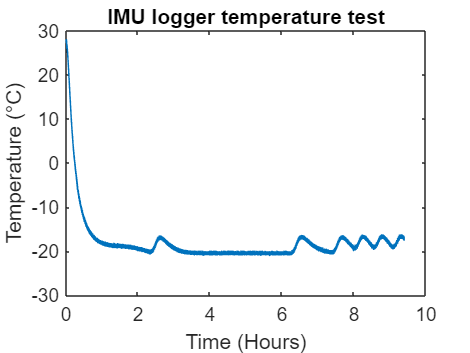

Fs = 105;

WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);

plot(hours(WaveTimeTable.Time), WaveTimeTable.Temperature);
title("IMU logger temperature test");
xlabel("Time (Hours)");
ylabel("Temperature (°C)");

## Error vs Freq at temp


f = linspace(0.03, 0.2, 1000)

f =     0.0300    0.0302    0.0303    0.0305    0.0307    0.0309    0.0310    0.0312    0.0314    0.0315    0.0317    0.0319    0.0320    0.0322    0.0324    0.0326    0.0327    0.0329    0.0331    0.0332    0.0334    0.0336    0.0337    0.0339    0.0341    0.0343    0.0344    0.0346    0.0348    0.0349    0.0351    0.0353    0.0354    0.0356    0.0358    0.0360    0.0361    0.0363    0.0365    0.0366    0.0368    0.0370    0.0371    0.0373    0.0375    0.0377    0.0378    0.0380    0.0382    0.0383


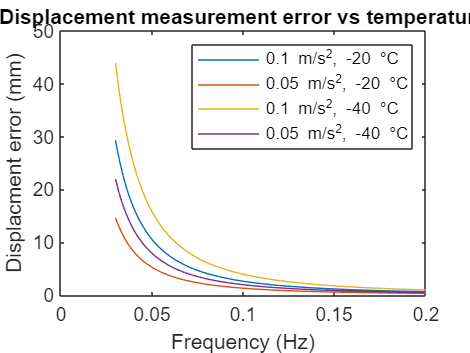

AccError1 = 0.1*0.026/100*40;
AccError2 = 0.05*0.026/100*40;
AccError3 = 0.1*0.026/100*60;
AccError4 = 0.05*0.026/100*60;

elevationError1 = AccError1./(2*pi*f).^2;
elevationError2 = AccError2./(2*pi*f).^2;
elevationError3 = AccError3./(2*pi*f).^2;
elevationError4 = AccError4./(2*pi*f).^2;

plot(f, elevationError1*1000, f, elevationError2*1000, f, elevationError3*1000, f, elevationError4*1000);
title("Displacement measurement error vs temperature");
xlabel("Frequency (Hz)");
ylabel("Displacment error (mm)");
legend("0.1 m/s^2, -20 °C", "0.05 m/s^2, -20 °C", "0.1 m/s^2, -40 °C",  "0.05 m/s^2, -40 °C");

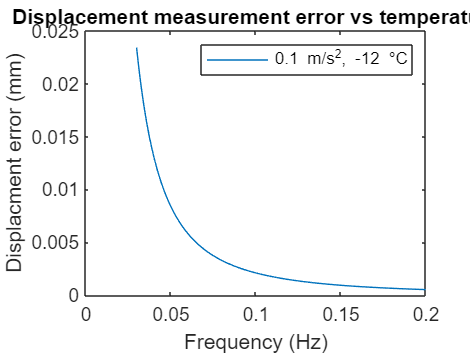


AccError5 = 0.1*0.026/100*32;
elevationError5 = AccError5./(2*pi*f).^2;

plot(f, elevationError5)
title("Displacement measurement error vs temperature");
xlabel("Frequency (Hz)");
ylabel("Displacment error (mm)");
legend("0.1 m/s^2, -12 °C");